clearvars; close('all')

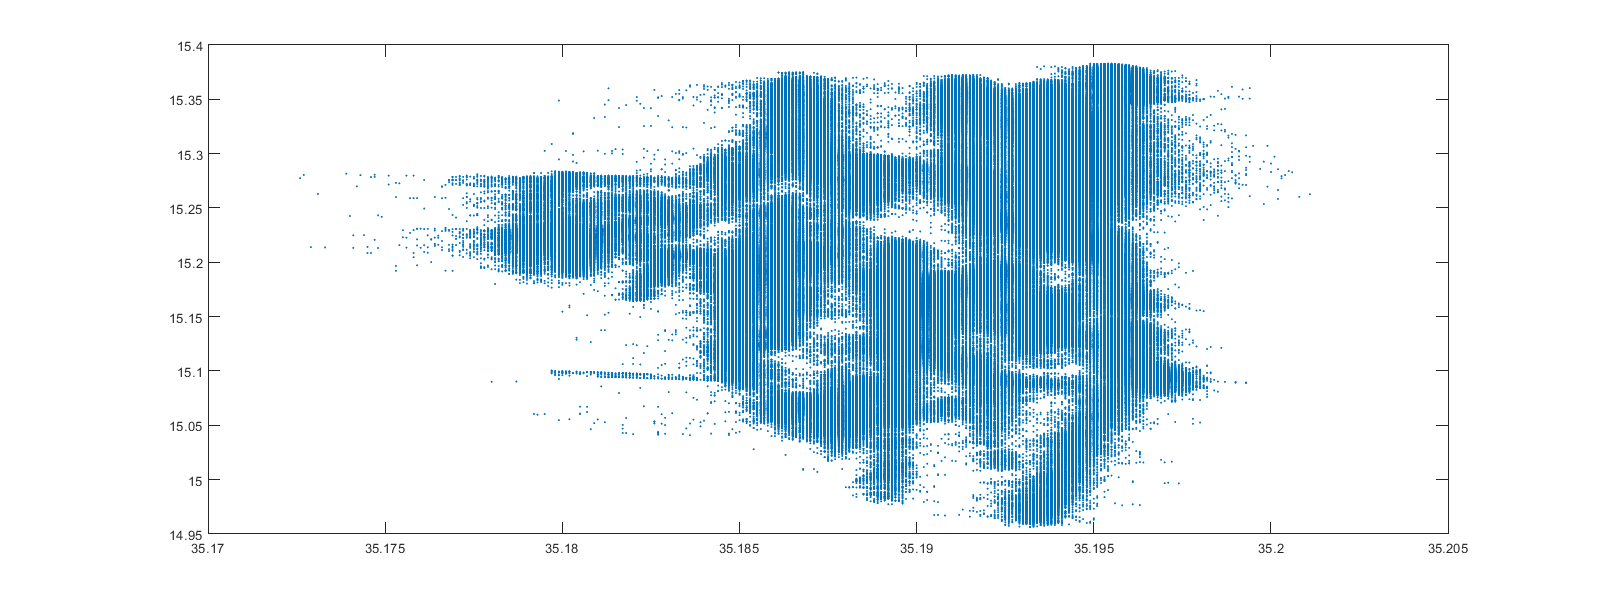

load SCAT_data_qc.mat
% replot figure
figure('Renderer', 'painters', 'Position', [10 20 1600 600])
salt=T.salt;
temp=T.temp;
plot(salt,temp,'.')

figure;
t = tiledlayout(3,1);
nexttile;
x=T.time;
y = salt;
[Y,dx,ndx] = ddspike(y,[-0.5 0.5],4,5,'n');

loop: 1;  spikes: 2472
loop: 2;  spikes: 2472
loop: 3;  spikes: 2472
loop: 4;  spikes: 2472
loop: 5;  spikes: 2472


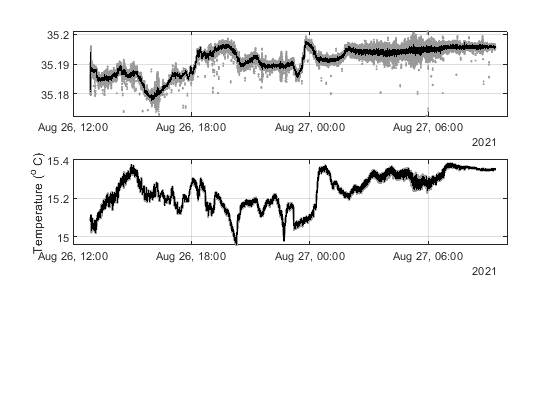

ix=Y==-9999;
Y(Y==-9999)=NaN;
h1=plot(x,Y,'b.','Color',[0.6 0.6 0.6]);
mmy=movmean(Y,30);
hold on
h2=plot(x,mmy,'k-');
title('')
ylabel('')
grid on

nexttile;
y = temp;
ix=Y==-9999;
y(Y==-9999)=NaN;
h1=plot(x,y,'b.','Color',[0.6 0.6 0.6]);
mmy=movmean(y,30);
hold on
h2=plot(x,mmy,'k-');
title('');
ylabel('Temperature (^o C)');
grid on



print(gcf,'-dpng',['figures/sal_example']);

## speed of sound

figure
plot(x,y,'b-');
hold on
plot([x(1) x(end)],[nanmean(y) nanmean(y)],'r-');
ylim([floor(min(y)) ceil(max(y))])
title('Speed of sound')
ylabel('m/s')

print(gcf,'-dpng',['figures/SOS_example']);